clear all
close all
clc

A1=8;
A2=12;
A3=12;


L(1) = Link('revolute','d',A1,'alpha',pi/2,'a',0,'offset',0);
L(2) = Link('revolute','d',0,'alpha',0,'a',A2,'offset',0); %eslabon 2 --> fila 2
L(3) = Link('revolute','d',0,'alpha',0,'a',A3,'offset',0);
L

 
L = 
 theta=q1, d=          8, a=          0, alpha=      1.571, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=         12, alpha=          0, offset=          0 (R,stdDH)
 theta=q3, d=          0, a=         12, alpha=          0, offset=          0 (R,stdDH)



%unir links 'eslabones'
proyecto3R = SerialLink(L,'name','3R')

 
proyecto3R = 
 
3R (3 axis, RRR, stdDH, fastRNE)                                 
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          8|          0|      1.571|          0|
|  2|         q2|          0|         12|          0|          0|
|  3|         q3|          0|         12|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 



proyecto3R.tool = transl(0,0,0)

 
proyecto3R = 
 
3R (3 axis, RRR, stdDH, fastRNE)                                 
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          8|          0|      1.571|          0|
|  2|         q2|          0|         12|          0|          0|
|  3|         q3|          0|         12|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


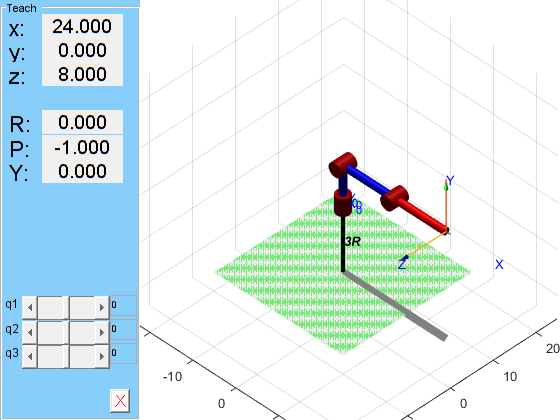



q = [0 0 0 ];  % Ángulos de las articulaciones

% Define el espacio de trabajo (ajusta los valores según sea necesario)
limites_espacio_trabajo = [-15 15 -15 15 -15 15];

proyecto3R.plot(q, 'workspace', limites_espacio_trabajo);

hold on 
trplot(eye(4),'rgb','length',1,'frame','0') % sistema coordenadas de la base 
axis([-25 25 -25 25 -25 25])% ajusta los ejes 
view(45, 40)% vista frente 
proyecto3R.teach()


q1=0;
q2=0;
q3=0;

TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 A1; 0 0 0 1]

TZ0 =      1     0     0     0
     0     1     0     0
     0     0     1     8
     0     0     0     1


RZ0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1]

RZ0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX1 = [1 0 0 0; 0 cos(pi/2) -sin(pi/2) 0; 0 sin(pi/2) cos(pi/2) 0; 0 0 0 1]

RX1 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


T01 =  TZ0*RZ0*TX1*RX1

T01 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    8.0000
         0         0         0    1.0000




TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ1 = [cos(q2) -sin(q2) 0 0; sin(q2) cos(q2) 0 0; 0 0 1 0; 0 0 0 1]

RZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX2 = [1 0 0 A2; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX2 =      1     0     0    12
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX2 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T12 =  TZ1*RZ1*TX2*RX2

T12 =      1     0     0    12
     0     1     0     0
     0     0     1     0
     0     0     0     1




TZ2 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ2 = [cos(q3) -sin(q3) 0 0; sin(q3) cos(q3) 0 0; 0 0 1 0; 0 0 0 1]

RZ2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX3 = [1 0 0 A3; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX3 =      1     0     0    12
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX3 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T23 =  TZ2*RZ2*TX3*RX3

T23 =      1     0     0    12
     0     1     0     0
     0     0     1     0
     0     0     0     1



T03 = T01*T12*T23

T03 =     1.0000         0         0   24.0000
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    8.0000
         0         0         0    1.0000
